close all;

% a sample on how to review data acquired from the RCV
json_string = fileread("" + ...
    "/home/robbe/llc_data_1.json" + ...
    "");
data = jsondecode(json_string)

data = 5807×1 struct array with fields:
    timestamp
    date
    time
    t_llc
    t_hlc
    t_bp
    t_ss
    t_bm_1
    t_bm_2
    t_bm_3
    t_bm_4
    t_esc_1
    t_esc_2
    t_esc_3
    t_esc_4
    i_ss
    i_llc
    i_hlc
    roll
    pitch
    yaw
    w
    i
    j
    k
    rpm_wheel_1
    rpm_wheel_2
    rpm_wheel_3
    rpm_wheel_4
    rpm_bm_1
    rpm_bm_2
    rpm_bm_3
    rpm_bm_4
    latitude
    longitude
    velocity
    altitude
    v_cell_1
    v_cell_2
    v_cell_3
    v_cell_4
    v_batt
    v_llc
    v_hlc
    v_phrp_3v3
    ch_1
    ch_2
    ch_3
    ch_4
    ch_5
    ch_6
    ch_7
    ch_8
    ch_9
    ch_10
    ch_11
    ch_12
    ch_13
    ch_14
    pwm_bm_1
    pwm_bm_2
    pwm_bm_3
    pwm_bm_4
    pwm_ss
    c_s
    failsafe
    dead_switch
    i_esc_1
    i_esc_2
    i_esc_3
    i_esc_4



length(data)

ans = 5807

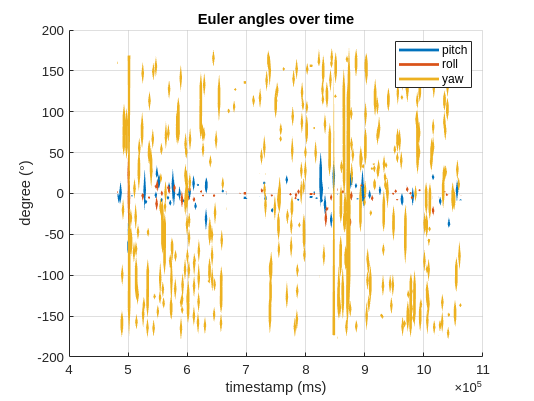


figure();
hold on;
plot([data(:).timestamp], [data(:).pitch],'LineWidth',2);
plot([data(:).timestamp], [data(:).roll],'LineWidth',2);
plot([data(:).timestamp], [data(:).yaw],'LineWidth',2);
xlabel("timestamp (ms)");
ylabel("degree (°)");
title("Euler angles over time");
legend("pitch", "roll", "yaw")
grid('on');
hold off;

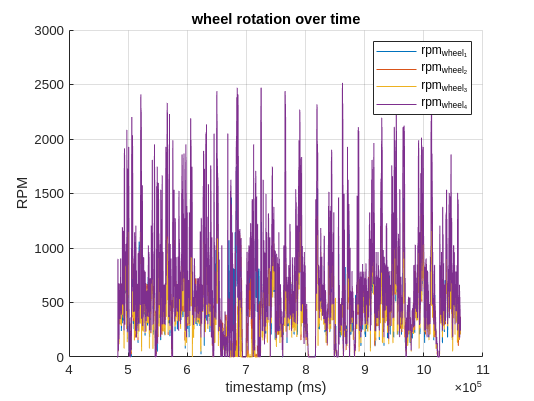


figure();
hold on;
plot([data(:).timestamp], [data(:).rpm_wheel_1]);
plot([data(:).timestamp], [data(:).rpm_wheel_2]);
plot([data(:).timestamp], [data(:).rpm_wheel_3]);
plot([data(:).timestamp], [data(:).rpm_wheel_4]);
xlabel("timestamp (ms)");
ylabel("RPM");
title("wheel rotation over time");
legend("rpm_{wheel_1}", "rpm_{wheel_2}", "rpm_{wheel_3}", "rpm_{wheel_4}")
grid('on');
hold off;

## Trajectory

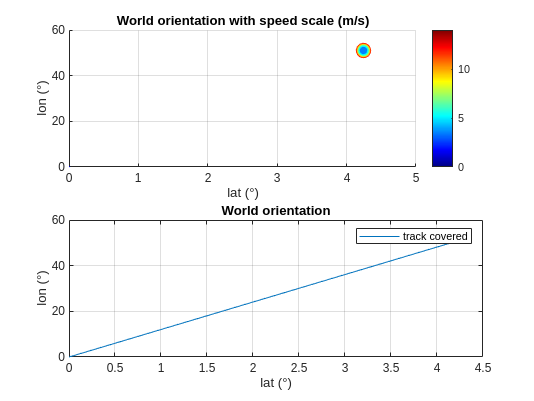

close all;

% Good gps plots are
% 13-04-2025/take_1/llc_data_4.json
% 13-04-2025/take_1/llc_data_8.json
% 13-04-2025/take_1/llc_data_7.json -> Needs some data cleaning where the
% lat and long become 0 which fuckes up the plot.

f=figure();

start = 1;
stop = 1600;

colors = jet(max([data(start:stop).velocity]+1));	% Initialize
colors = colors([data(start:stop).velocity]+1,:); % Colored according to distance.

subplot(2,1,1);
scatter([data(start:stop).longitude], [data(start:stop).latitude], ([data(start:stop).velocity]*10 + 1),colors, 'filled');
xlabel("lat (°)");
ylabel("lon (°)");
title("World orientation with speed scale (m/s)");
grid('on');
set(f,'Colormap',jet);
clim([0,max([data(start:stop).velocity]+1)])
colorbar();

subplot(2,1,2);
plot([data(start:stop).longitude], [data(start:stop).latitude]);
xlabel("lat (°)");
ylabel("lon (°)");
title("World orientation");
legend("track covered");
grid('on');